# 调试噪声增强器

clc,clear,close all
dsPath="C:\Users\P1900\OneDrive\桌面\作业\数据科学\酒水识别\data\shake\train";

ads = audioDatastore(dsPath,IncludeSubfolders=true,LabelSource="foldernames");
[adsTrain,adsValidation] = splitEachLabel(ads,0.7,0.3);

adsTrain = transform(adsTrain,@RandomNoise,'IncludeInfo',true);
adsTrain = transform(adsTrain,@BackgroundNoise,'IncludeInfo',true);
tic
[x,fileInfo] = read(adsTrain);
toc

历时 0.541208 秒。


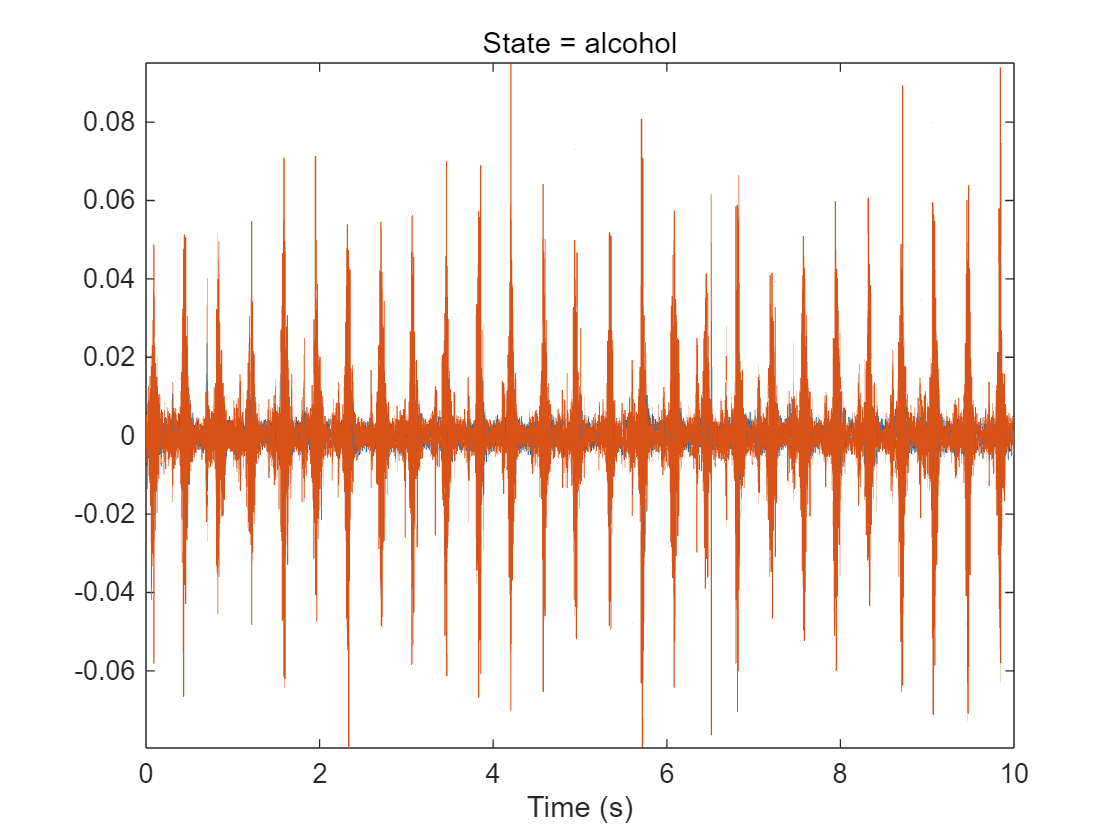

fs = fileInfo.SampleRate;
reset(adsTrain)

% sound(x,fs)

figure
t = (0:size(x,1)-1)/fs;
plot(t,x)
xlabel("Time (s)")
title("State = " + string(fileInfo.Label))
axis tight